clear all;
close all;

Euler's method

Delta_t=0.2;
t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    x(n+1)=x(n)-Delta_t*(x(n).^2);
end
 
plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


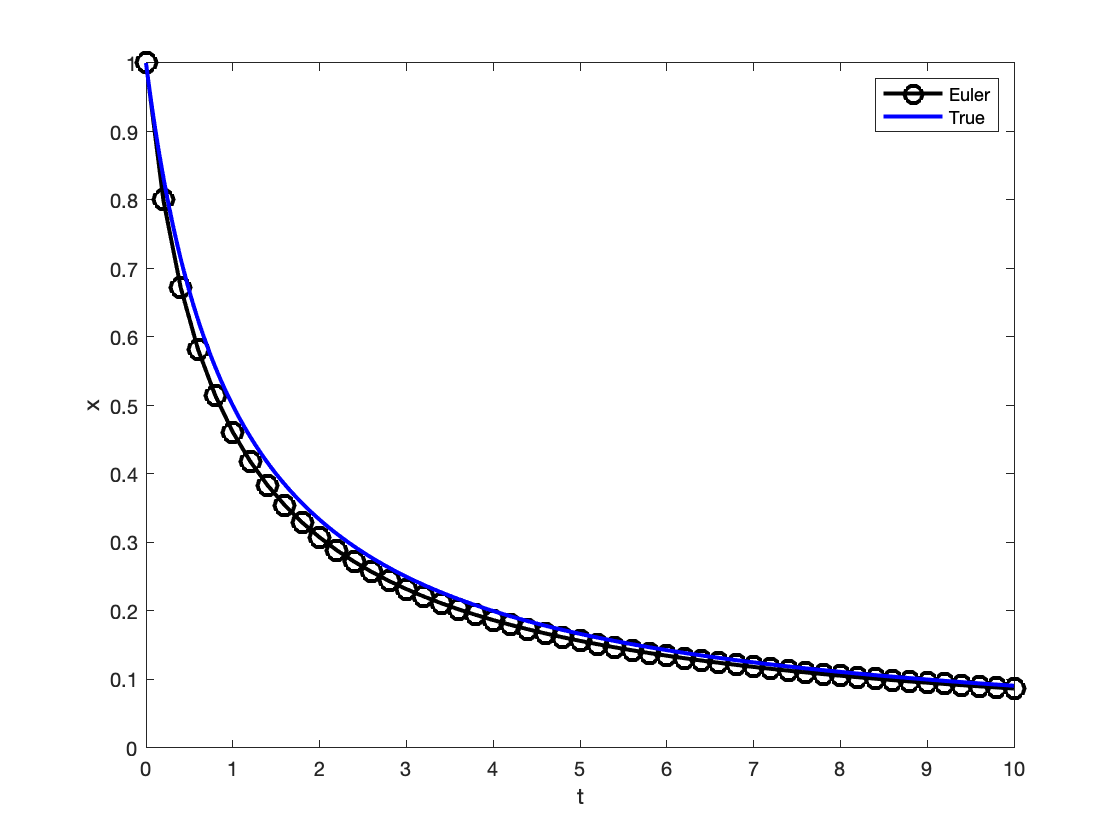

plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('Euler','True');
axis([0 10 0 1])

Taylor's method order 2

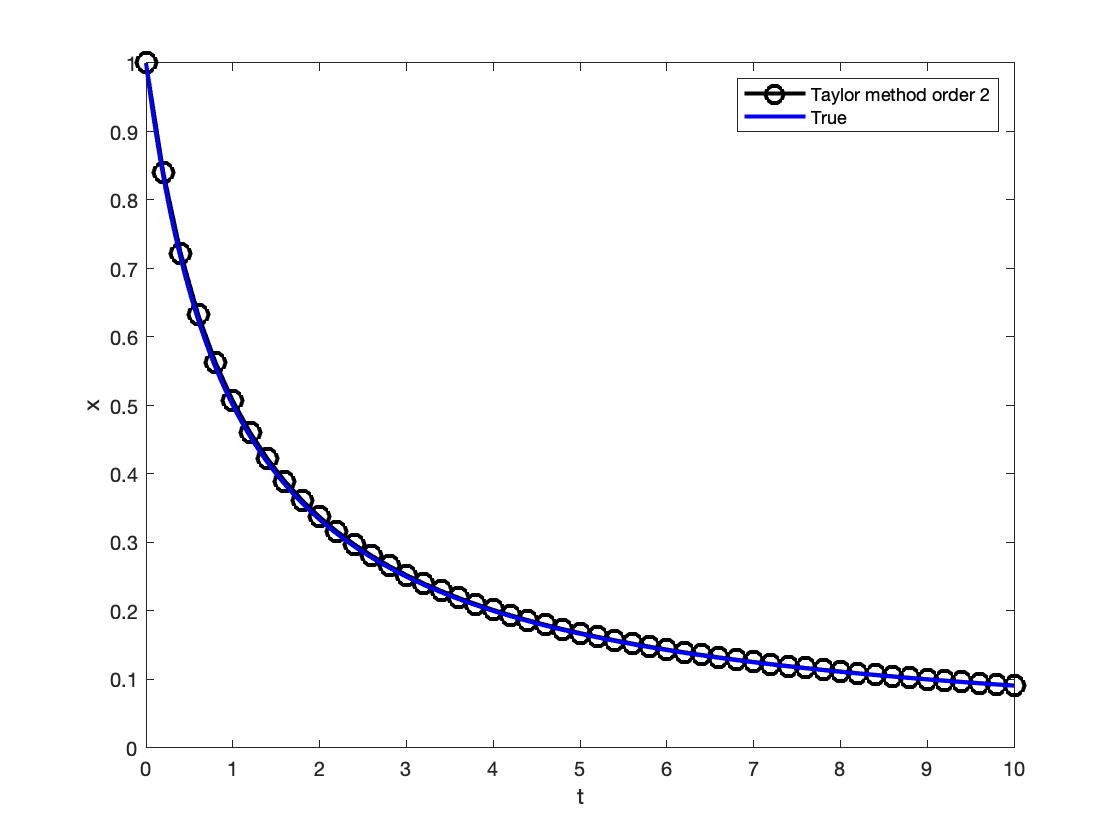

t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    x(n+1)=x(n)-Delta_t*(x(n).^2)+2*(Delta_t.^2/2)*(x(n).^3);
end

hold off

plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('Taylor method order 2','True');
axis([0 10 0 1])